## Upload the big dataset (>250MB) to MATLAB Drive and read table

BitcoinData = readtable('bitcoin-dataset.csv');

Tablesize = size(BitcoinData)

Tablesize =      4857377           8


head(BitcoinData,1)

ans = 1×8 table
    Timestamp     Open    High    Low     Close    Volume__BTC_    Volume__Currency_    Weighted_Price
    __________    ____    ____    ____    _____    ____________    _________________    ______________

    1.3253e+09    4.39    4.39    4.39    4.39       0.45558               2                 4.39     


## Convert timestamp

datetest = BitcoinData(:,1);
datetest = table2array(datetest);
BitcoinData.Timestamp = datetime(datetest, 'ConvertFrom', 'posixtime');

## Remove NaNs

% how many NaNs in each column
NaN2 = sum(isnan(BitcoinData.Open))

NaN2 = 1243608

NaN3 = sum(isnan(BitcoinData.High))

NaN3 = 1243608

NaN4 = sum(isnan(BitcoinData.Low))

NaN4 = 1243608

NaN5 = sum(isnan(BitcoinData.Close))

NaN5 = 1243608

NaN6 = sum(isnan(BitcoinData.Volume__BTC_))

NaN6 = 1243608

NaN7 = sum(isnan(BitcoinData.Volume__Currency_))

NaN7 = 1243608

NaN8 = sum(isnan(BitcoinData.Weighted_Price))

NaN8 = 1243608


% remove NaNs
BitcoinData = BitcoinData(isnan(BitcoinData.High) == 0,:);

## Select data

BitcoinDataTimetable = table2timetable(BitcoinData);

% March 2013
% S = timerange('17-Mar-2013 00:00:00','18-Mar-2013 23:59:00'); %2days
% S = timerange('17-Mar-2013 00:00:00','23-Mar-2013 23:59:00'); %7days
% S = timerange('17-Mar-2013 00:00:00','30-Mar-2013 23:59:00'); %14days

% March 2016
% S = timerange('17-Mar-2016 00:00:00','18-Mar-2016 23:59:00'); %2days
% S = timerange('17-Mar-2016 00:00:00','23-Mar-2016 23:59:00'); %7days
% S = timerange('17-Mar-2016 00:00:00','30-Mar-2016 23:59:00'); %14days

% March 2019
% S = timerange('17-Mar-2019 00:00:00','18-Mar-2019 23:59:00'); %2days
% S = timerange('17-Mar-2019 00:00:00','23-Mar-2019 23:59:00'); %7days
% S = timerange('17-Mar-2019 00:00:00','30-Mar-2019 23:59:00'); %14days

% March 2021
% S = timerange('17-Mar-2021 00:00:00','18-Mar-2021 23:59:00'); %2days
% S = timerange('17-Mar-2021 00:00:00','23-Mar-2021 23:59:00'); %7days
% S = timerange('17-Mar-2021 00:00:00','30-Mar-2021 23:59:00'); %14days

BitcoinData = BitcoinDataTimetable(S,:);
Tablesize = size(BitcoinData)

Tablesize =         9238           7


## Create model - preprocessing

% standardization, and Initial predictor set (matrix)

Y = BitcoinData{:,"Close"}

Y = 	1.0e+03 *

    3.9900
    3.9899
    3.9909
    3.9924
    3.9902
    3.9918
    3.9922
    3.9922
    3.9919
    3.9919



X = BitcoinData{:,[1:3]}

X = 	1.0e+03 *

    3.9900    3.9900    3.9900
    3.9900    3.9900    3.9899
    3.9900    3.9918    3.9900
    3.9910    3.9924    3.9899
    3.9902    3.9902    3.9902
    3.9914    3.9918    3.9914
    3.9922    3.9922    3.9922
    3.9909    3.9922    3.9909
    3.9919    3.9919    3.9919
    3.9919    3.9919    3.9919



%Check model for outliers

LRPre = fitlm(zscore(X),Y)

LRPre = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE          tStat       pValue
                   ________    _________    __________    ______

    (Intercept)     3982.2     0.0075273    5.2904e+05      0   
    x1             -11.004       0.17707       -62.146      0   
    x2              15.787       0.13494        116.99      0   
    x3              16.163       0.12102        133.55      0   


Number of observations: 9238, Error degrees of freedom: 9234
Root Mean Squared Error: 0.723
R-squared: 0.999,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 2.58e+06, p-value = 0

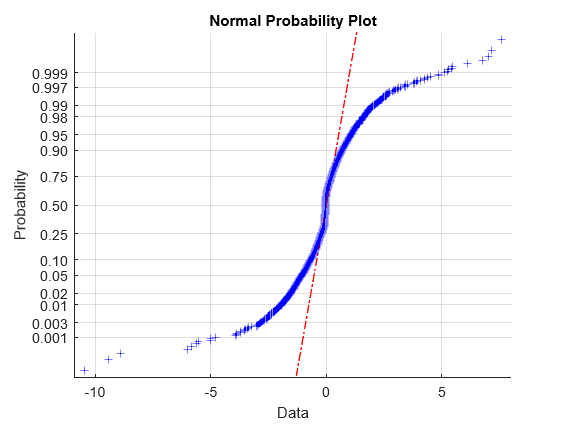


normplot(LRPre.Residuals.Raw)

## Identify and Remove Outliers

idx = isoutlier(BitcoinData.Close)

idx = 9238×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


sum(idx)

ans = 347

BitcoinData(idx,:) = []

BitcoinData = 8891×7 timetable
         Timestamp           Open      High      Low      Close     Volume__BTC_    Volume__Currency_    Weighted_Price
    ____________________    ______    ______    ______    ______    ____________    _________________    ______________

    17-Mar-2019 00:00:00      3990      3990      3990      3990        1.6034             6397.7              3990    
    17-Mar-2019 00:01:00      3990      3990    3989.9    3989.9       0.95321             3803.3              3990    
    17-Mar-2019 00:02:00      3990    3991.8      3990    3990.9        2.0498             8180.2            3990.8    
    17-Mar-2019 00:04:00    


%outliers = outlier(BitcoinData.Close)

%Rerun model to check for more outliers
Y = BitcoinData{:,"Close"}

Y = 	1.0e+03 *

    3.9900
    3.9899
    3.9909
    3.9924
    3.9902
    3.9918
    3.9922
    3.9922
    3.9919
    3.9919



X = BitcoinData{:,[1:3]}

X = 	1.0e+03 *

    3.9900    3.9900    3.9900
    3.9900    3.9900    3.9899
    3.9900    3.9918    3.9900
    3.9910    3.9924    3.9899
    3.9902    3.9902    3.9902
    3.9914    3.9918    3.9914
    3.9922    3.9922    3.9922
    3.9909    3.9922    3.9909
    3.9919    3.9919    3.9919
    3.9919    3.9919    3.9919




LRPre = fitlm(zscore(X),Y)

LRPre = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE          tStat       pValue
                   ________    _________    __________    ______

    (Intercept)     3980.2     0.0075428    5.2768e+05      0   
    x1             -10.042       0.15985       -62.822      0   
    x2              14.256       0.12321        115.71      0   
    x3              14.238       0.10724        132.76      0   


Number of observations: 8891, Error degrees of freedom: 8887
Root Mean Squared Error: 0.711
R-squared: 0.999,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 1.99e+06, p-value = 0

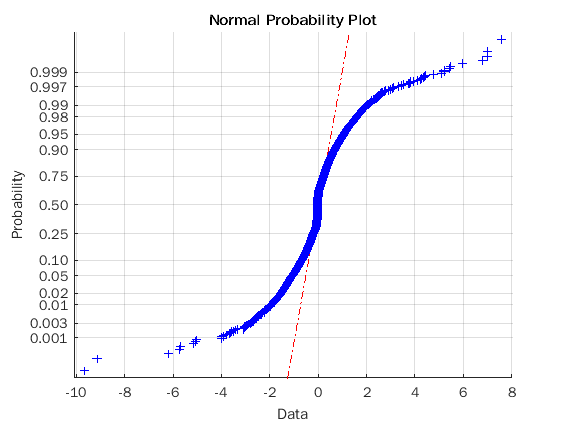


normplot(LRPre.Residuals.Raw)


idx = isoutlier(BitcoinData.Close)

idx = 8891×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


sum(idx)

ans = 215

BitcoinData(idx,:) = []

BitcoinData = 8676×7 timetable
         Timestamp           Open      High      Low      Close     Volume__BTC_    Volume__Currency_    Weighted_Price
    ____________________    ______    ______    ______    ______    ____________    _________________    ______________

    17-Mar-2019 00:00:00      3990      3990      3990      3990        1.6034             6397.7              3990    
    17-Mar-2019 00:01:00      3990      3990    3989.9    3989.9       0.95321             3803.3              3990    
    17-Mar-2019 00:02:00      3990    3991.8      3990    3990.9        2.0498             8180.2            3990.8    
    17-Mar-2019 00:04:00    


%outliers = outlier(BitcoinData.Close)

## Split dataset into training and testing data

BitcoinData_new = [X, Y];

PD = 0.20;
cv = cvpartition(size(BitcoinData_new,1),'HoldOut',PD);
Xtrain = BitcoinData_new(cv.training,[1:end - 1]);
Ytrain = BitcoinData_new(cv.training,end);
Xtest = BitcoinData_new(cv.test, [1:end - 1]);
Ytest = BitcoinData_new(cv.test,end);

## Linear model with training-testing split

LRModel = fitlm(zscore(Xtrain),Ytrain)

LRModel = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE          tStat       pValue
                   ________    _________    __________    ______

    (Intercept)     3980.2     0.0081407    4.8892e+05      0   
    x1             -10.047        0.1757       -57.181      0   
    x2              14.289       0.13628        104.85      0   
    x3              14.126       0.12173        116.04      0   


Number of observations: 7113, Error degrees of freedom: 7109
Root Mean Squared Error: 0.687
R-squared: 0.999,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 1.69e+06, p-value = 0

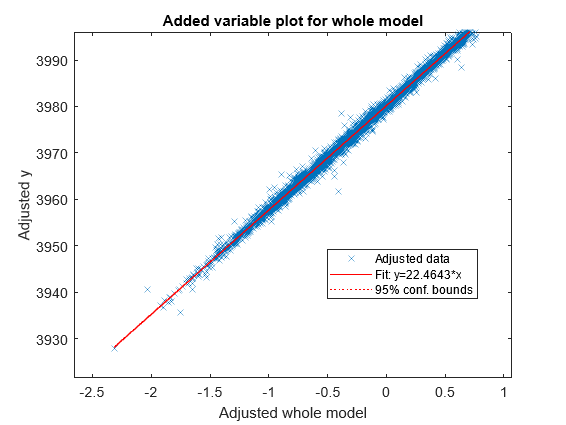


plot(LRModel)

LRModel.RMSE

ans = 0.6866

## Predict

[YPred, Scores] = predict(LRModel,Xtest)

YPred = 	1.0e+04 *

    7.7273
    7.7203
    7.7227
    7.7192
    7.6767
    7.6996
    7.6980
    7.6982
    7.6734
    7.6839


Scores = 	1.0e+04 *

    7.7209    7.7337
    7.7139    7.7266
    7.7163    7.7291
    7.7128    7.7256
    7.6703    7.6830
    7.6933    7.7060
    7.6916    7.7043
    7.6918    7.7045
    7.6671    7.6797
    7.6776    7.6902


## Plots

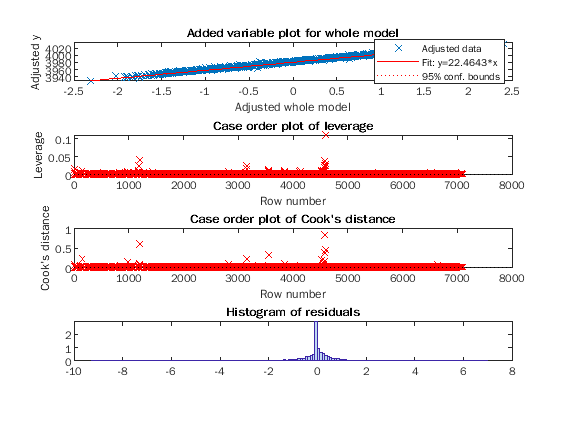

figure, 
subplot(4, 1, 1), plot(LRModel)
subplot(4, 1, 2), plotDiagnostics(LRModel)
subplot(4, 1, 3), plotDiagnostics(LRModel, 'cookd')
subplot(4, 1, 4), plotResiduals(LRModel)

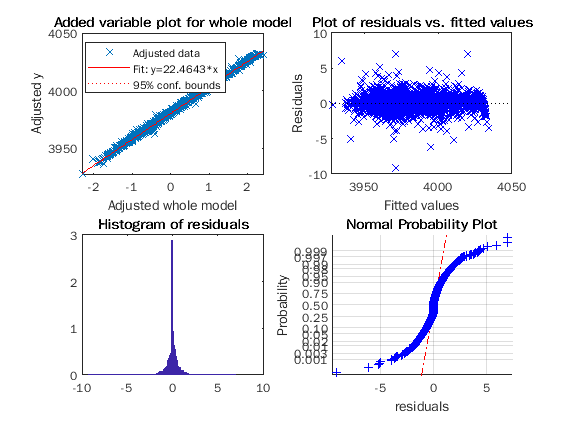


figure, 
subplot(2, 2, 1), plot(LRModel)
subplot(2, 2, 2), plotResiduals(LRModel,'fitted')
subplot(2, 2, 3), plotResiduals(LRModel)
subplot(2, 2, 4), normplot(LRModel.Residuals.Raw)
xlabel('residuals')